# MHB for delays

### Settings

clear vars; close all; clc
format long
global A B C G P Az fre nn gamma x_eq W tau

nn = 3;           % number of ring cells
flag = 2;         % 0 - regular ring, 1 - NONregular network, 2 - directed network
mp = 1.0;
ifi = 0;
tend = 1000;      % time 

### Network Structure

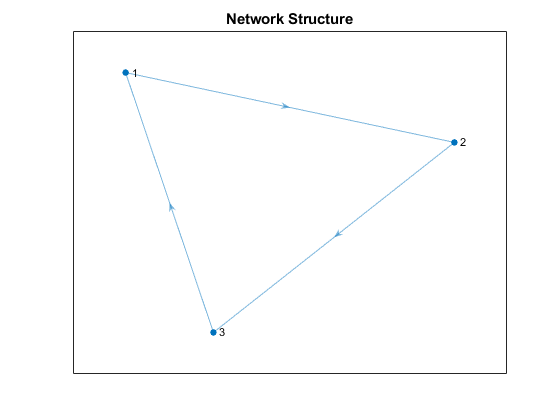

[G,n,offset] = NetworkStructure(nn,flag);

In=eye(n);

### Individual dynamics

%% Parameters
    
b = 0.08;   

A = [-0.8*b b; -1 1];
B = [0; 1];
C = [0 1];
P = [0; -0.559];


### Equilibrium point(s) and Linearizaton

syms x1 x2 z1 z2 s zu
assume (x1, 'real')
assume (x2, 'real')
assume (z1, 'real')
assume (z2, 'real')

x = [x1;x2];
z = [z1;z2];
J(x) = jacobian(A*x + P + B*C*(-1/3)*x.^3);
eqp = solve((A*x + P + B*C*(-1/3)*x.^3==0),x);
x_eq = [double(eqp.x1); double(eqp.x2)];
J0 = double(J(eqp.x1, eqp.x2));
huzwitzCrit(J0)

System is Stable


### Change of coordinates to zero equlibria

Az = [-0.8*b b; -1 (1-x_eq(2)^2)];

J1(z)=jacobian(Az*z + B*C*((-1/3)*z.^3 - x_eq(2)*z.^2));
eqp1 = solve((Az*z + B*C*((-1/3)*z.^3 - x_eq(2)*z.^2)==0),z);
z_eq = [double(eqp1.z1); double(eqp1.z2)];
J01 = double(J1(eqp1.z1, eqp1.z2));
huzwitzCrit(J01)

System is Stable


### Bifurcation point(s)

H(s) = C*((s*eye(length(J01)) - J01)^-1)*B;
H(s) = simplify(H(s));

w = 0:0.0001:1;

L = double(H(1i*w'));

[nu,i] = min(real(L));

om_star = w(i)

om_star =    0.420200000000000


gamma_min = -1/(2*nu)

gamma_min =    2.537620723891215



BC = B*C;

AA = kron(In,(J01-gamma_min*BC));
BB = kron(gamma_min*G,BC);

% eq1 = det(kronsum((AA + BB*zu),(AA'+ BB'*(1/zu))));
% crit1 = double(solve(eq1==0,zu));
% crit1m=[];
% f1=[];
% for i = 1:length(crit1)
%     ei = eig(AA + BB*crit1(i));
%     for ii = 1:length(ei)
%         if abs(real(ei(ii)))<10e-6 && imag(ei(ii))>0 
%             crit1m = [crit1m; crit1(i)];
%             f1 = [f1; imag(ei(ii))];
%         end
%     end   
% end
% 
% taus = sort((-1i*log(1./crit1m))./f1);
% taus = real(taus(taus>0))
% %return

### Most rigth eigenvalue of linearization

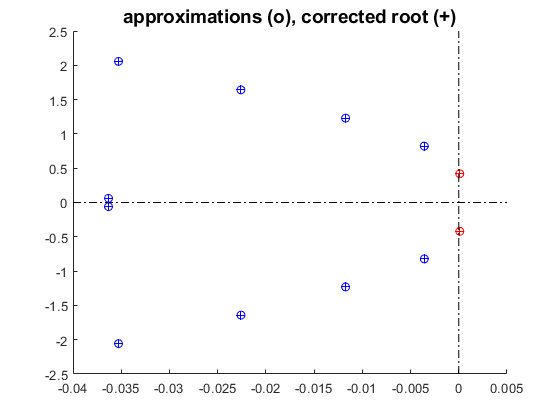


addpath('files_roots')  
% 
%  gamma =1.1*gamma_min;
%  tau = taus(1);

gamma = 3;
tau = 4.8;

A0 = kron(In,(J01 - gamma*B*C));
A1 = kron(gamma*G,B*C);
hA = [0, tau];

tds = tds_create({A0, A1}, hA);
tds_check_valid(tds)
options=tdsrootsoptions;
options.minimal_real_part= -0.04;
[eigenvalues, N, size_eigenvalue_problem]=tds_charateristic_roots(tds, options);
figure
eigenplot(eigenvalues)

eigenvalues.l1

ans =   0.000105267931638 + 0.420061223801888i
  0.000105267931638 - 0.420061223801888i
 -0.003576707171407 + 0.822633014924534i
 -0.003576707171407 - 0.822633014924534i
 -0.011727310659600 + 1.230638822450223i
 -0.011727310659600 - 1.230638822450223i
 -0.022582036806085 + 1.641856221798570i
 -0.022582036806085 - 1.641856221798570i
 -0.035299570608566 + 2.055926941042447i
 -0.035299570608566 - 2.055926941042447i


eigenvalues.l0

ans =   0.000105269439207 + 0.420061225611078i
  0.000105269439207 - 0.420061225611078i
 -0.003577090774802 + 0.822632406283493i
 -0.003577090774802 - 0.822632406283493i
 -0.011736975058940 + 1.230585763133093i
 -0.011736975058940 - 1.230585763133093i
 -0.022583993603777 + 1.641476111104064i
 -0.022583993603777 - 1.641476111104064i
 -0.035277775155824 + 2.057067609946419i
 -0.035277775155824 - 2.057067609946419i



if real(eigenvalues.l1(1)) < 0
    return
end

fre = imag(eigenvalues.l1(1))

fre =    0.420061223801888


### DDE Simulation Zero equlibria

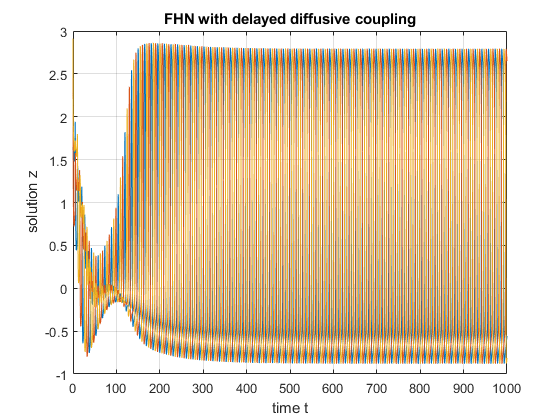


tic

options = ddeset('RelTol',1e-3);
sol = dde23(@FHM_zeroeq,tau,@ddex1hist,[0, tend],options);
% sol1 = dde23(@FHM_zeroeq,tau,@ICnearzero,[0, 2000],options);


dde_z = kron(eye(n),C)*sol.y;
dde_zs = dde_z + fliplr(offset)';
time = sol.x;

% dde_z1 = kron(eye(n),C)*sol1.y;
% dde_zs1 = dde_z1 + fliplr(offset)';
% time1 = sol1.x;

figure;
plot(time,dde_z)
title('FHN with delayed diffusive coupling');
xlabel('time t');
ylabel('solution z');
grid on


toc

Elapsed time is 9.856251 seconds.



[omega_s, T_s, amp_s, fi_s, DC_s] = osciprof(dde_z,time,n);

Frequency is equal to 0.41224
Period is equal to 15.2414
DC is 
   0.561430835425945
   0.556983653373299
   0.556295390246607

Amplitudes are equal to 
   2.239309840507779
   2.243732928273777
   2.243540194188821

The phase shift is (RAD)
                   0
   2.096866555377983
   4.188061820975607

The phase shift is (DEG)
   1.0e+02 *

                   0
   1.201416038252934
   2.399582666817764




q_s = amp_s.*exp(1i*fi_s);
y_s = DC_s + q_s;
g_s = [fi_s;amp_s;DC_s;omega_s];


## Equal amplitude case

syms k_test_0 k_test_1 a b
om = fre

om =    0.420061223801888


omega=om;
W = C*((1i*om*eye(length(Az)) - Az)^-1)*B;
W0 = C*((0*eye(length(Az)) - Az)^-1)*B;

[v,lam]=eig(G,'vector');

lam_max=max(real(lam))

lam_max =    1.000000000000000



ii=1

ii =      1



kappa0 = (-gamma*lam(3)*W0 + gamma*W0 + 1)/W0

kappa0 =    1.210836102250925



[omega_test, kappa_1] = kappaFre_FNM(Az,B,C,lam(ii),tau,om,gamma)

ei =  -0.035654386013355 - 0.186088606295460i
 -0.000000768998212 + 0.420154162358777i


omega_test =   -0.420154162358777


kappa_1 =   -0.001673000006459



assume(a,'real')
assume(b,'real')

eqs = [49*b/50-b^2/3-a^2/2+49*a^2/(100*b)==kappa0, -a^2/4-b^2+49*b/25==kappa_1];
solutions = solve(eqs, a, b);


DC = double(solutions.a)

DC =    1.884381362521448


amp = double(solutions.b)

amp =    0.707328549070658



LKI = lam(ii)*In-gamma*exp(-1i*om*tau)*G;

[vi,lamda]=eig(LKI,'vector');

q = vi(:,ii);
fi=angle(q)

fi =                    0
   2.094395102393193
  -2.094395102393197


fideg = rad2deg(fi)

fideg = 	1.0e+02 *

                   0
   1.199999999999999
  -1.200000000000001


disp('TEST')

TEST







% ii = 3
% 
% % assume(k_test,'real')
% % assume(k_test>0)
% 
% eque_0 = det(-Az + B*(-k_test_0*C + gamma*C - gamma*lam(ii)*C));
% DF0_val = double(solve(eque_0==0,k_test_0))
% 
% assume(k_test_1, 'real')
% eque_1 = det(-Az + B*(-k_test_1*C + gamma*C - gamma*exp(-1i*om*tau)*lam(1)*C));
% DF1_val = double(solve(eque_1==0,k_test_1))



